%******************************************************************************
% \details     : WST Lebensdauer von Neonröhren
% \autor       : Simon Burkhardt
% \file        : wst_experiment_3_neonroehren_live.mlx
% \date        : 23.02.2019
%******************************************************************************
clear all; close all; clc
format shorteng

data = [24 39 45 51 55 62 64 65 67 76 123];
data = sort(data);
n = length(data);

x_ = mean(data)      % Mittelwert

x_ =     61.0000e+000


sx = std(data)       % Standardabweichung

sx =     25.2507e+000



% Quartile
Q50 = median(data)   % Median

Q50 =     62.0000e+000


Q25 = quantile(data, 0.25)  % 0.25 Quartil

Q25 =     46.5000e+000


Q75 = quantile(data, 0.75)  % 0.75 Quartil

Q75 =     66.5000e+000


% % % stimmen nicht mit Abbildung 1.3.i überein
% % % Q25 = 45;
% % % Q75 = 67;

% Quartilsweite und Ausreissergrenzen (Kapitel 2.5.2)
dQ = Q75 - Q25;
A_unten = Q25 - 1.5*dQ

A_unten =     16.5000e+000


A_oben  = Q75 + 1.5*dQ

A_oben =     96.5000e+000


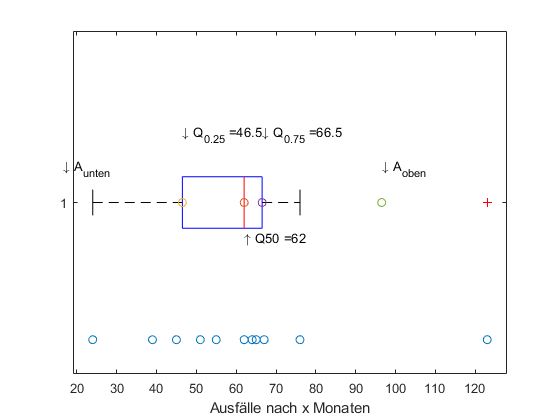


figure(1)
boxplot(data, 'orientation', 'horizontal', 'whisker', 1.5)
% Die Whisker werden von Matlab an den falschen Orten Platziert, auch mit
% Verlängerung auf 3 stimmen diese nie mit den berechneten Grenzen überein
xlabel('Ausfälle nach x Monaten')
ylabel('')

% Beschriftung der Grenzen
text(Q50, 0.9, strcat('\uparrow Q50 = ', num2str(Q50)))
text(Q25, 1.2, strcat('\downarrow Q_{0.25} = ', num2str(Q25,4)))
text(Q75, 1.2, strcat('\downarrow Q_{0.75} = ', num2str(Q75,4)))
text(A_unten, 1.1, strcat('\downarrow A_{unten}'))
text(A_oben, 1.1, strcat('\downarrow A_{oben}'))

% Grenzen genau markieren
hold on;
plot(data, 0.6.*ones(1,length(data)), 'o');
plot(Q50, 1, 'o')
plot(Q25, 1, 'o')
plot(Q75, 1, 'o')
plot(A_oben, 1, 'o')
plot(A_unten, 1, 'o')